# Brain cancer classification

## Point to data set

You can change `pathToImages` to point to the data set

pathToImages = "./datasets";

## Get training and testing images

Create datastore using subfolder names

imgs = imageDatastore(pathToImages + "/Training","IncludeSubfolders",true,"LabelSource","foldernames",'ReadFcn',@cropToLargestContour);
testImgs = imageDatastore(pathToImages + "/Testing", "IncludeSubfolders", true, "LabelSource", "foldernames",'ReadFcn',@cropToLargestContour);

[trainImgs, validationImgs] = splitEachLabel(imgs, 0.8, 'randomize');

Data augmentation

augmenter = imageDataAugmenter( ...
    'RandXReflection', true, ...
    'RandYReflection', true, ...
    'RandRotation', [-30,30], ...
    'RandXTranslation', [-10 10], ...
    'RandYTranslation', [-10 10], ...
    'RandScale', [0.8 1.2]);
augTrainImgs = augmentedImageDatastore([224 224 3],trainImgs,"ColorPreprocessing","gray2rgb","DataAugmentation",augmenter);
augValidationImgs = augmentedImageDatastore([224 224 3],validationImgs,"ColorPreprocessing","gray2rgb");
augTestImgs = augmentedImageDatastore([224 224 3],testImgs,"ColorPreprocessing","gray2rgb");

Determine the all the brain tumor types, number of train and test images

numClasses = numel(categories(trainImgs.Labels));
numTrain = numel(augTrainImgs.Files);
numTest = numel(augTestImgs.Files);
numValidation = numel(augValidationImgs.Files);
disp(['Number of train images: ', num2str(numTrain)]);

Number of train images: 2297


disp(['Number of validation images: ', num2str(numValidation)]);

Number of validation images: 573


disp(['Number of test images: ', num2str(numTest)]);

Number of test images: 394


disp(['Number of brain tumor types: ', num2str(numClasses)]);

Number of brain tumor types: 4


## Create a network by modifying GoogLeNet, EfficientNet-b0, Xception

You could also do these steps in the Deep Network Designer.

Get the layers from GoogLeNet

flag_net = 1; % 1, 2, 3 is equivalent to googlenet, efficientnetb0, and xception

if flag_net == 1
    net = googlenet
    fully_connected_layer = 'loss3-classifier';
    output_layer = 'output';
elseif flag_net == 2
    net = efficientnetb0
    fully_connected_layer = 'efficientnet-b0|model|head|dense|MatMul';
    output_layer = 'classification';
elseif flag_net == 3
    net = xception
    fully_connected_layer = 'predictions';
    input_layer = 'input_1';
    output_layer = 'ClassificationLayer_predictions';
end

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}



lgraph = layerGraph(net);

Modify the classification and output layers

newFc = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
newOutput = classificationLayer("Name","new_out");

lgraph = replaceLayer(lgraph,fully_connected_layer,newFc);
lgraph = replaceLayer(lgraph,output_layer,newOutput);

if flag_net == 3
    newInput = imageInputLayer([224,224,3], 'Name', 'input');
    lgraph = replaceLayer(lgraph, input_layer, newInput);
end

## Perform training

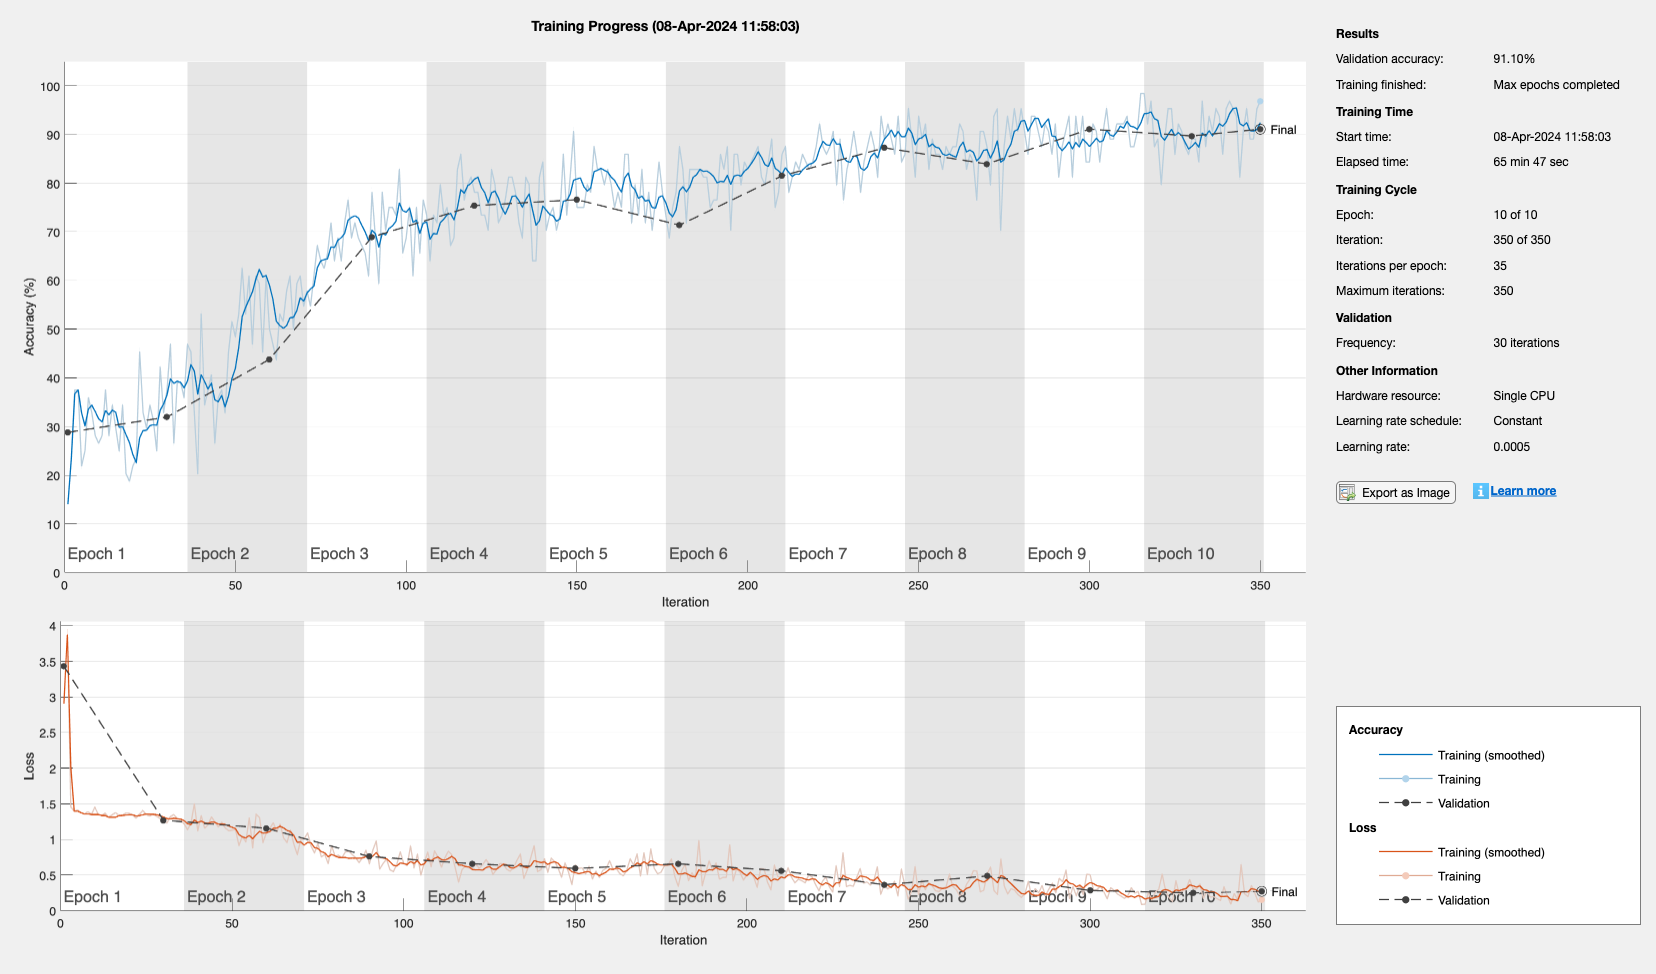

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.0005, ...
    'MaxEpochs', 10, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augValidationImgs, ...
    'ValidationFrequency', 30, ...
    'Verbose', false, ...
    'MiniBatchSize', 64, ...
    'Plots', 'training-progress');
[cancernet, info] = trainNetwork(augTrainImgs,lgraph, options);

if flag_net == 1
    train_googlenet = cancernet
elseif flag_net == 2
    train_efficientnetb0 = cancernet
elseif flag_net == 3
    train_xception = cancernet
end

train_xception =   DAGNetwork with properties:

         Layers: [170×1 nnet.cnn.layer.Layer]
    Connections: [181×2 table]
     InputNames: {'input'}
    OutputNames: {'new_out'}


## Use the trained network to classify test images

testpreds = classify(cancernet,augTestImgs)

testpreds = 394×1 categorical array
     glioma_tumor 
     no_tumor 
     meningioma_tumor 
     glioma_tumor 
     glioma_tumor 
     meningioma_tumor 
     no_tumor 
     no_tumor 
     meningioma_tumor 
     no_tumor 
     no_tumor 
     no_tumor 
     pituitary_tumor 
     meningioma_tumor 
     meningioma_tumor 
     no_tumor 
     no_tumor 
     meningioma_tumor 
     glioma_tumor 
     meningioma_tumor 
     no_tumor 
     meningioma_tumor 
     meningioma_tumor 
     no_tumor 
     no_tumor 
     no_tumor 
     glioma_tumor 
     no_tumor 
     meningioma_tumor 
     no_tumor 


tic
toc

Elapsed time is 0.002074 seconds.


## Evaluate the results

Calculate the accuracy

accuracy = nnz(testpreds == testImgs.Labels)/numel(testpreds)

accuracy = 0.7995

Visualize the confusion matrix, compute average sensitivity and specificity

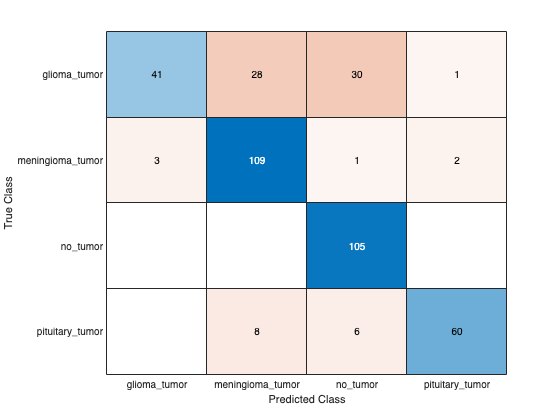

confusionchart(testImgs.Labels,testpreds);

% Confusion matrix
confMat = confusionmat(testImgs.Labels, testpreds);

% Initialize arrays to store precision and recall for each class
numClasses = numel(categories(testImgs.Labels));
sensitiviy = zeros(numClasses, 1);
specificity = zeros(numClasses, 1);

% Calculate sensitivity and specificity for each class
for i = 1:numClasses
    TP = confMat(i, i);
    FP = sum(confMat(:, i)) - TP;
    FN = sum(confMat(i, :)) - TP;
    TN = sum(confMat(:)) - TP - FP - FN;
    
    sensitiviy(i) = TP / (TP + FN);
    specificity(i) = TN / (TN + FP);
end

% Display the results
fprintf('Average Sensitivity: %.4f\n', mean(sensitiviy, 'omitnan'));

Average Sensitivity: 0.7922


fprintf('Average Specificity: %.4f\n', mean(specificity, 'omitnan'));

Average Specificity: 0.9308
